# Visualizing the HYG Star Database

*By Paul Kassebaum*

*pkassebaum@gmail.com*

Source of data: https://github.com/astronexus/HYG-Database/raw/master/hygdata_v3.csv

Fields in the database:

- id: The database primary key.

- hip: The star's ID in the Hipparcos catalog, if known.

- hd: The star's ID in the Henry Draper catalog, if known.

- hr: The star's ID in the Harvard Revised catalog, which is the same as its number in the Yale Bright Star Catalog.

- gl: The star's ID in the third edition of the Gliese Catalog of Nearby Stars.

- bf: The Bayer / Flamsteed designation, primarily from the Fifth  Edition of the Yale Bright Star Catalog. This is a combination of the  two designations. The Flamsteed number, if present, is given first; then a three-letter abbreviation for the Bayer Greek letter; the Bayer  superscript number, if present; and finally, the three-letter  constellation abbreviation. Thus Alpha Andromedae has the field value  "21Alp And", and Kappa1 Sculptoris (no Flamsteed number) has "Kap1Scl".

- ra, dec: The star's right ascension and declination, for epoch and equinox 2000.0.

- proper: A common name for the star, such as "Barnard's Star" or  "Sirius". I have taken these names primarily from the Hipparcos  project's web site, which lists representative names for the 150  brightest stars and many of the 150 closest stars. I have added a few  names to this list. Most of the additions are designations from catalogs mostly now forgotten (e.g., Lalande, Groombridge, and Gould ["G."])  except for certain nearby stars which are still best known by these  designations.

- dist: The star's distance in parsecs, the most common unit in  astrometry. To convert parsecs to light years, multiply by 3.262. A  value >= 10000000 indicates missing or dubious (e.g., negative)  parallax data in Hipparcos.

- pmra, pmdec:  The star's proper motion in right ascension and declination, in milliarcseconds per year.

- rv:  The star's radial velocity in km/sec, where known.

- mag: The star's apparent visual magnitude.

- absmag: The star's absolute visual magnitude (its apparent magnitude from a distance of 10 parsecs).

- spect: The star's spectral type, if known.

- ci: The star's color index (blue magnitude - visual magnitude), where known.

- x,y,z: The Cartesian coordinates of the star, in a system based on  the equatorial coordinates as seen from Earth. +X is in the direction of the vernal equinox (at epoch 2000), +Z towards the north celestial  pole, and +Y in the direction of R.A. 6 hours, declination 0 degrees.

- vx,vy,vz: The Cartesian velocity components of the star, in the same coordinate system described immediately above. They are determined from the proper motion and the radial velocity (when known). The velocity  unit is parsecs per year; these are small values (around 1 millionth of a parsec per year), but they enormously simplify calculations using  parsecs as base units for celestial mapping.

- rarad, decrad, pmrarad, prdecrad:  The positions in radians, and proper motions in radians per year.

- bayer:  The Bayer designation as a distinct value

- flam:  The Flamsteed number as a distinct value

- con:  The standard constellation abbreviation

- comp, comp_primary, base:  Identifies a star in a multiple star  system.  comp = ID of companion star, comp_primary = ID of primary star  for this component, and base = catalog ID or name for this multi-star  system.  Currently only used for Gliese stars.

- lum:  Star's luminosity as a multiple of Solar luminosity.

- var:  Star's standard variable star designation, when known.

- var_min, var_max:  Star's approximate magnitude range, for  variables.  This value is based on the Hp magnitudes for the range in  the original Hipparcos catalog, adjusted to the V magnitude scale to  match the "mag" field.

This visualization was inspired by [this figure](https://raw.githubusercontent.com/zonination/h-r-diagram/master/twinkle.gif) by [u/zonination](https://www.reddit.com/user/zonination).

Set up a datastore.

filename = 'hygdata_v3.csv';
ds = datastore(filename);

Focus on the absolute visual magnitude and color index data fields.

ds.SelectedVariableNames = {'absmag','ci'};

Create a tall table of the data.

tbl = tall(ds);

Draw a two variable histogram.

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 5 sec
Evaluation completed in 7 sec
Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 4 sec
Evaluation completed in 5 sec


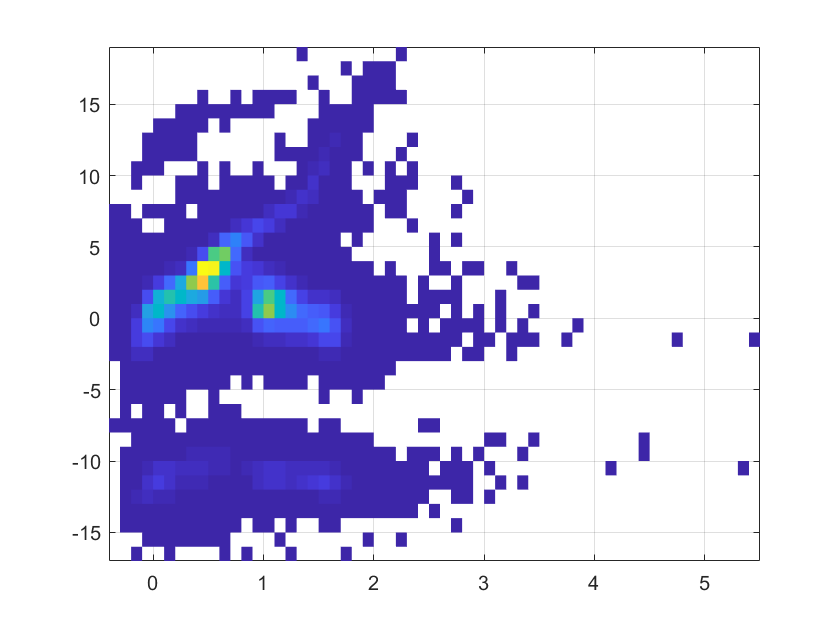

h = histogram2(tbl.ci,tbl.absmag,'DisplayStyle','tile');

Customize the figure.

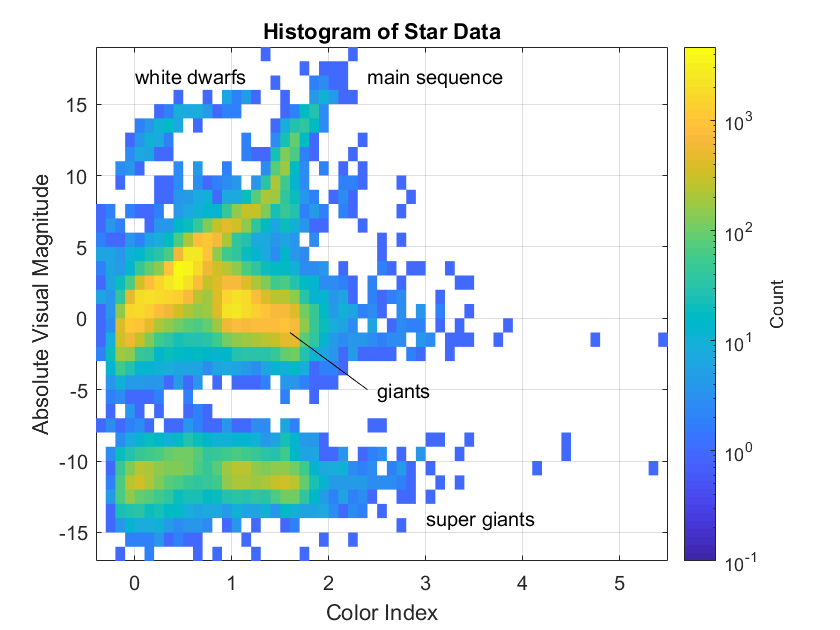

xlabel('Color Index');
ylabel('Absolute Visual Magnitude');
title('Histogram of Star Data');

ax = gca;
ax.ColorScale = 'log';

cb = colorbar;
cb.Label.String = 'Count';

text(0, 17,'white dwarfs');

text(2.4, 17,'main sequence');
% line([2.4 1.49],[10 9.5],'Color','black');

text(2.5,-5,'giants');
line([2.4 1.6],[-5 -1],'Color','black');

text(3,-14,'super giants');

Save the figure as a PNG.

print('ci_vs_absmag','-dpng');